# Time series and spectral analysis

## Structure of time series

Wave like structure is the most commonly used tool to analyze time series. The periodicity of the time series can characterise the behaviour of the given process.  

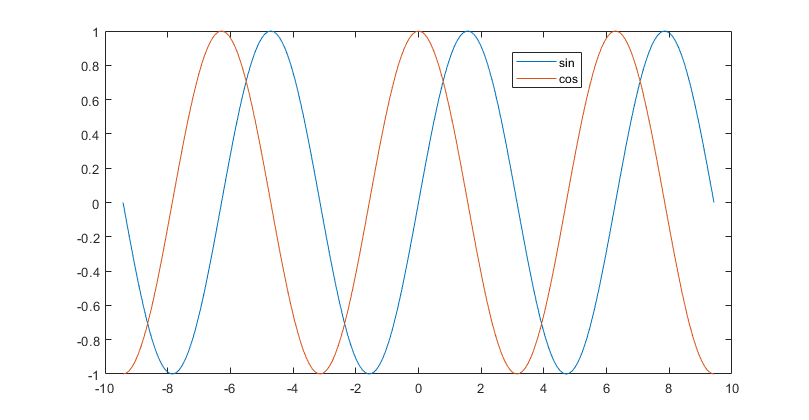

**Reproduce the above graphs**.

%t=
%f1=sin()
%f2=cos()
%plot(t, , t, )

## Fourier series: periodic functions

Virtually any function with the period $p$ can be expressed as a sum of sine and cosine functions. A periodic function has this property,


$$f(x) = f(x+kp)$$


where $k$ takes integer values $0, \pm 1, \pm 2$,.. 

Then such a function can be expressed as the following infinite sum,


$$
f(x) = \sum_{n=0}^{\infty} \left[ a_n \cos{(2\pi n x / p)}  + b_n \sin{(2\pi n x / p)}\right]
$$


where $a_n$ and $b_n$ are constants that may be determined by the function $f(x)$. A simplest example of a periodic process is the sine/cosine function.


$$\sin{x} = \sin{(x+k2\pi)}$$


The sine function has the period of $2\pi$. In a more general form, a sinusoidal function is given by


$$A\sin{\omega x}$$


where the priod is $p=2\pi/\omega$, and $\omega = 2\pi / p$ is called the angular frequency, and $A$ is called the amplitude.

### Square Wave from Sine Waves

The Fourier series for a square wave is: $f(t)=\sum_{n=1}^{\infty}\frac{\sin((2n-1)t)}{2n-1}$

This example shows (graphically) how the Fourier series expansion for a square wave is made up of a sum of odd harmonics.

We start by forming a time vector running from 0 to 10 in steps of 0.1, and take the sine of all the points. Let's plot this fundamental frequency.

% t = 0:.1:10;
% y = sin(t);
% figure
% plot(t,y);

Now add the third harmonic to the fundamental, and plot it.

% y = sin(t) + sin(3*t)/3;
% plot(t,y);

Now use the first, third, fifth, seventh, and ninth harmonics.

% y = sin(t) + sin(3*t)/3 + sin(5*t)/5 + sin(7*t)/7 + sin(9*t)/9;
% plot(t,y);

For a finale, we will go from the fundamental to the 19th harmonic, creating vectors of successively more harmonics, and saving all intermediate steps as the rows of a matrix.

These vectors are plotted on the same figure to show the evolution of the square wave. Note that Gibbs' effect says that it will never really get there.

% t = 0:.02:3.14;
% y = zeros(10,length(t));
% x = zeros(size(t));
% for k = 1:2:19
%    x = x + sin(k*t)/k;
%    y((k+1)/2,:) = x;
% end
% plot(y(1:2:9,:)')
% title('The building of a square wave: Gibbs'' effect')

## Example of sinusoidal input/output and added noise

Consider a sum of three sinusoidal waves. Such a wave form can be generated by the following codes.

% Generate example time series
t = 0:1/1000:0.2-1/1000; 
% Sampled at 1 ms for .2 sec. Make the sample number even. 
% This works better for FFT. Sampled at 200 points.

% 3 frequencies
w1 = 2*pi*100;
w2 = 2*pi*120;
w3 = 2*pi*130;

% 3 amplitudes
A1 = 1;
A2 = 1/2;
A3 = 1/3;

% combine the sinusoides
f1 = A1*sin(w1*t);
f2 = A2*sin(w2*t);
f3 = A3*sin(w3*t);
f = f1+f2+f3;

The resulting wave can be plotted

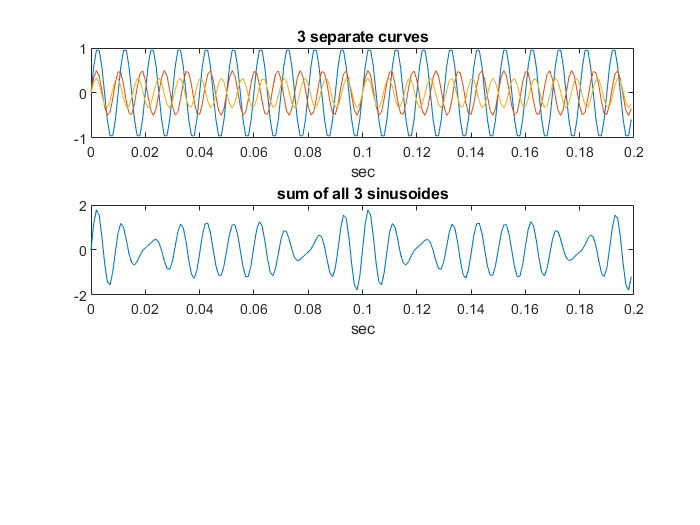

figure
% plot the graphs
subplot(3,1,1), plot(t,f1,t,f2,t,f3)
title('3 separate curves')
xlabel('sec')
subplot(3,1,2), plot(t,f)
title('sum of all 3 sinusoides')
xlabel('sec')

Now add Gaussian noise to the wave, then the wave form will have little apparent pattern and will be hard to analyze without the help of the Fourier transform.

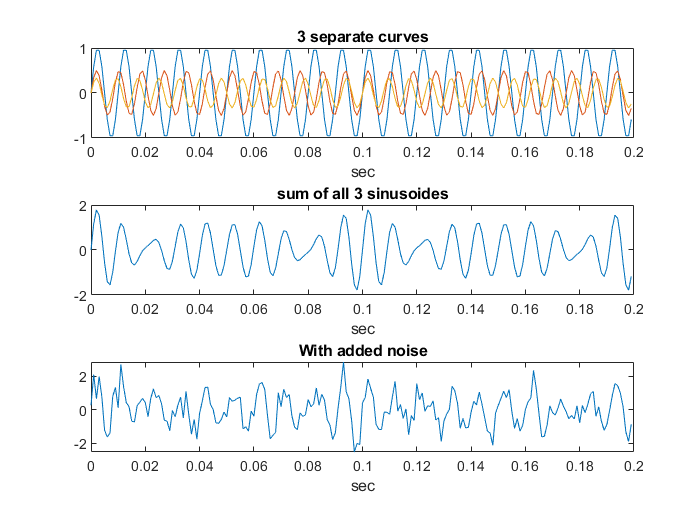

% Add gaussian noise mean = 0, var = 0.1
rng default
Noise = 0.5*randn(1,length(t));

subplot(3,1,3), plot(t,f+Noise)
title('With added noise')
xlabel('sec')

Now use fft to find the frequency components and the amplitudes for the wave without added noise.

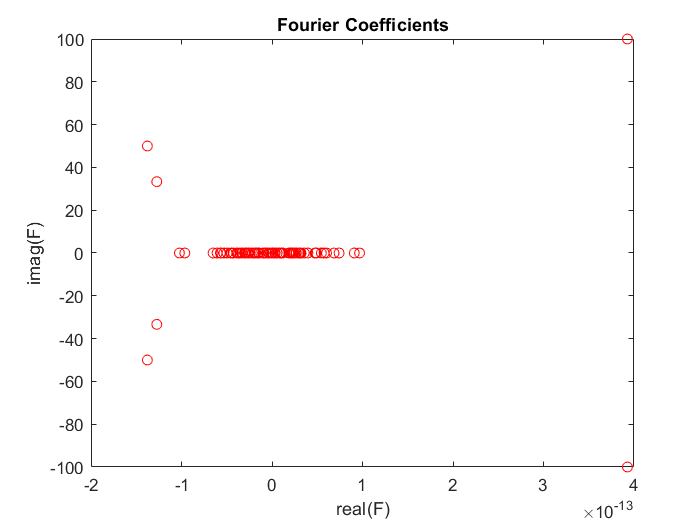

figure
% recover the frequencies and amplitudes for the wave without noise
F = fft(f);
plot(F,'r o') %Plot of 200 complex numbers with real parts on horizontal axis and imaginary 
% part on vertical axis. 
xlabel('real(F)')
ylabel('imag(F)')
title('Fourier Coefficients')

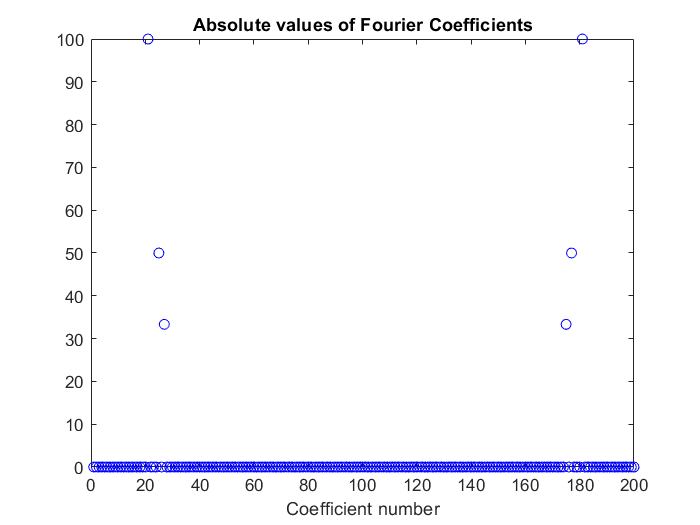


figure
plot(abs(F), 'b o') % Absolute values of complex numbers versus number of complex number 
title('Absolute values of Fourier Coefficients'); 
xlabel('Coefficient number')

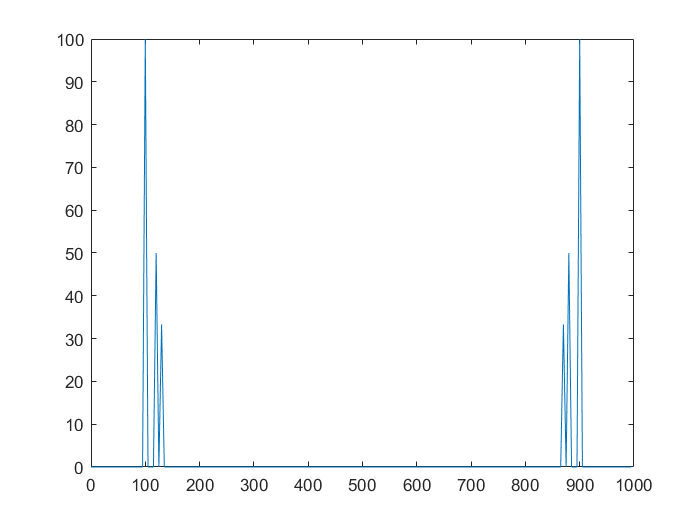


W = (0:length(F)-1)*1000/length(F);
plot(W,abs(F))

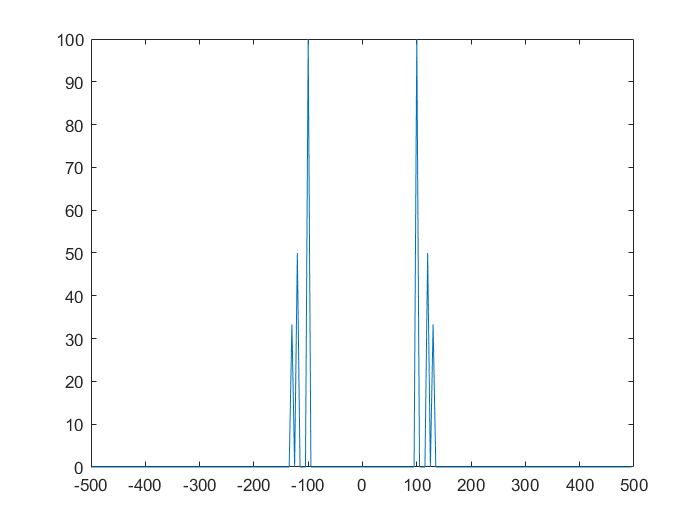

n = length(t);                         
fshift = (-n/2:n/2-1)*(1000/n);
yshift = fftshift(F);
plot(fshift,abs(yshift))

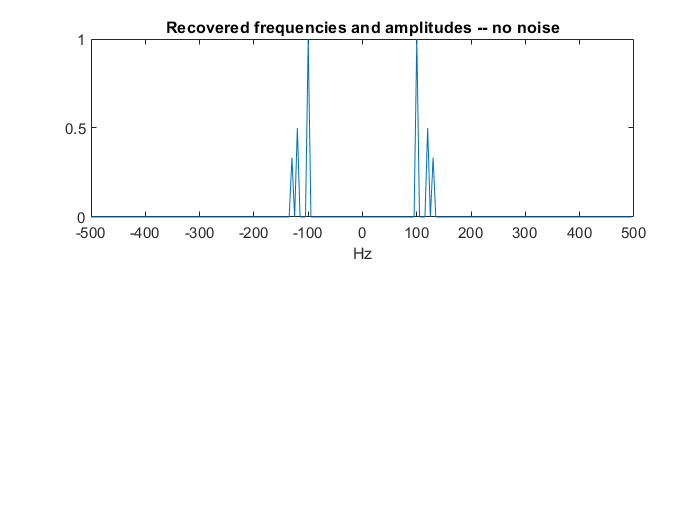

subplot(2,1,1), plot(fshift,abs(yshift)/n*2)
% the fft is normalized to get the correct values of the amplitudes.
xlabel('Hz')
title('Recovered frequencies and amplitudes -- no noise')

Now use fft to find the frequency components and the amplitudes for the wave with added noise.

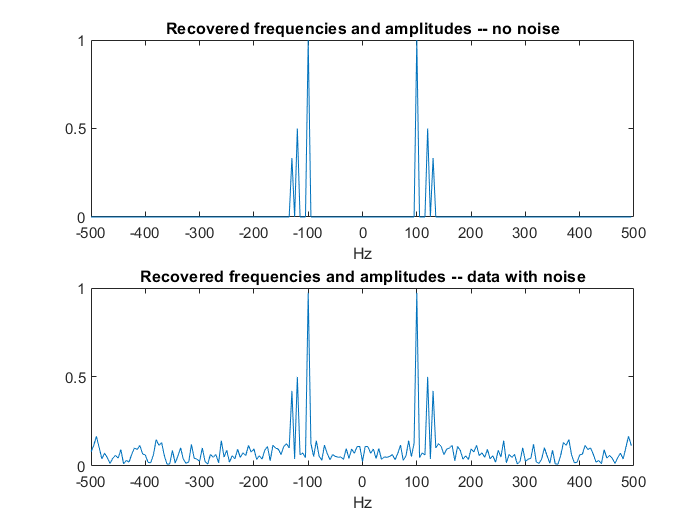

%recover the frequencies and amplitudes for the wave with noise
FN=fft(f+Noise);
%W = (0:length(F)-1)*1000/length(F);
n = length(t);                         
fshift = (-n/2:n/2-1)*(1000/n);
ynshift=fftshift(FN);
subplot(2,1,2), plot(fshift,abs(ynshift)/n*2)
% the fft is normalized to get the correct values of the amplitudes.
xlabel('Hz')
title('Recovered frequencies and amplitudes -- data with noise')

*Question: What will happen if the sinusoides are shifted in phase randomly?*

## Power Spectral Density (PSD) function

*Definition: Power spectra - Spectral analysis finds applications in many diverse fields. In vibration monitoring, the spectral content of measured signals give information on the wear and other characteristics of mechanical parts under study. In economics, meteorology, astronomy and several other fields, the spectral analysis may reveal ``hidden periodicities'' in the studied data, which are to be associated with cyclic behavior or recurring processes. In speech analysis, spectral models of voice signals are useful in better understanding the speech production process, and -- in addition -- can be used for both speech synthesis (or compression) and speech recognition. In radar and sonar systems, the spectral contents of the received signals provide information on the location of the sources (or targets) situated in the field of view. In medicine, spectral analysis of various signals measured from a patient, such as electrocardiogram (ECG) or electroencephalogram (EEG) signals, can provide useful material for diagnosis. In seismology, the spectral analysis of the signals recorded prior to and during a seismic event (such as a volcano eruption or an earthquake) gives useful information on the ground movement associated with such events and may help in predicting them. Seismic spectral estimation is also used to predict subsurface geologic structure in gas and oil exploration. In control systems, there is a resurging interest in spectral analysis methods as a means of characterizing the dynamical behavior of a given system, and ultimately synthesizing a controller for that system. (Spectral analysis of signals by P. Stoica and R. Moses) *

## Practical computation of PSD or Autocorrelation function

Energy : 


$$E = \int_{-\infty}^{\infty} | X(t) |^2 \, dt$$
 

Conveniently this integral has the equivalent for the Fourier transform of $X(t)$, say $\Xi (f)$.

 
$$E = \int_{-\infty}^{\infty} | X(t) |^2 \, dt =  \int_{-\infty}^{\infty} | \Xi (f) |^2 \, df$$


So, $S(f) =  | \Xi (f) |^2$ is called the power spectral density function, which can used to characterize the function $X(t)$. In summary, one can obtain the PSD by taking the Fourier transform of the time-series and then squaring it.

## Rlationship between Autocorrelation and Power Spectral Density functions

The PSD and the associated autocorrelation function are Fourier transform pair, that is, on is the Fourier transform of the other. They have the relationship depicted in the figure below.

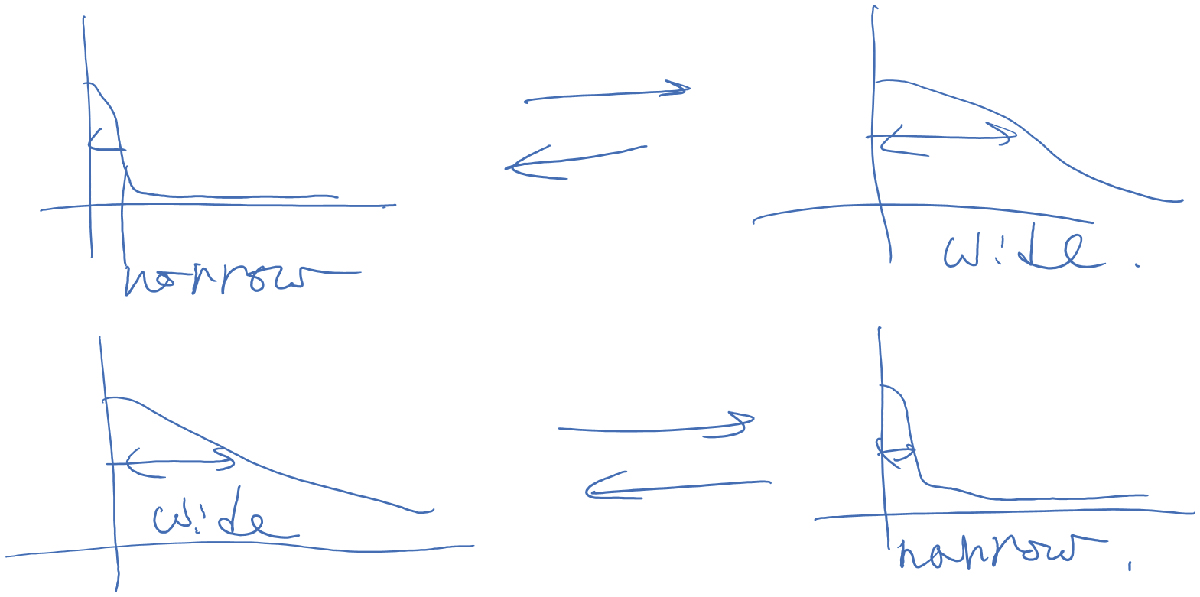

Note that most natural phenomena have the bell-shaped autocorrelation, that is, influence diminishes as the distance or time grows. The Fourier transform preserves the bell shape, only the width of the curve changes.

## Using Welch PSD Estimate of Signal with Frequency in Hertz

Create a signal consisting of a 100 Hz sinusoid in additive $N(0,1)$ white noise. Reset the random number generator for reproducible results. The sample rate is 1 kHz and the signal is 5 seconds in duration.

rng default  % Initializing the random number generator.

fs = 1000; % Sampling frequency in Hz
t = 0:1/fs:5-1/fs;  % Make the sample number even for FFT work nicely
x = cos(2*pi*100*t)+randn(size(t)); % Adding gaussian noise

Obtain Welch's overlapped segment averaging PSD estimate of the preceding signal. Use a segment length of 500 samples with 300 overlapped samples. Use 500 DFT points so that 100 Hz falls directly on a DFT bin. Input the sample rate to output a vector of frequencies in Hz. Plot the result.

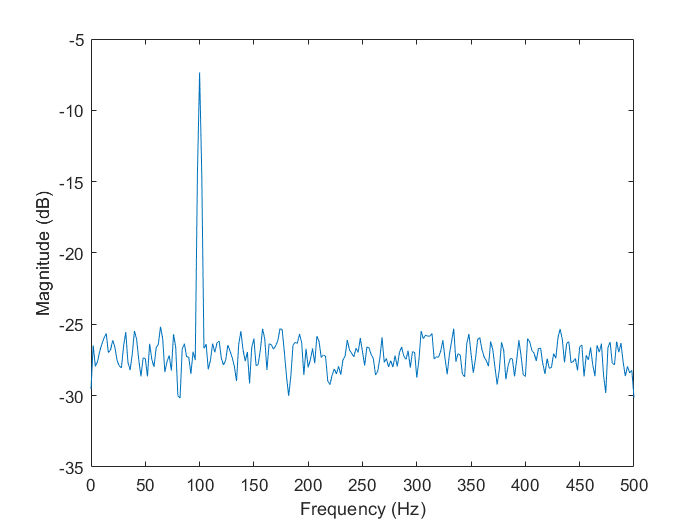

figure
[pxx,f] = pwelch(x,500,300,500,fs);

plot(f,10*log10(pxx))

xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')

*Copyright 2015 The MathWorks, Inc. Edited by h. chung 2018*

## Power Spectral Density Estimates Using FFT

This example shows how to obtain nonparametric power spectral density (PSD) estimates equivalent to the periodogram using `fft`. The examples show you how to properly scale the output of `fft` for even-length inputs, for normalized frequency and hertz, and for one- and two-sided PSD estimates.

## Even-Length Input with Sample Rate

Obtain the periodogram for an even-length signal sampled at 1 kHz using both `fft` and `periodogram`. Compare the results.

Create a signal consisting of a 100 Hz sine wave in *N*(0,1) additive noise. The sampling frequency is 1 kHz. The signal length is 1000 samples. Use the default settings of the random number generator for reproducible results.

rng default
Fs = 1000; % Sampling frequency. This can change depending on the data.
t = 0:1/Fs:1-1/Fs;
x = cos(2*pi*100*t) + randn(size(t));

Obtain the periodogram using `fft`. The signal is real-valued and has even length. Because the signal is real-valued, you only need power estimates for the positive or negative frequencies. In order to conserve the total power, multiply all frequencies that occur in both sets -- the positive and negative frequencies -- by a factor of 2. Zero frequency (DC) and the Nyquist frequency do not occur twice. Plot the result.

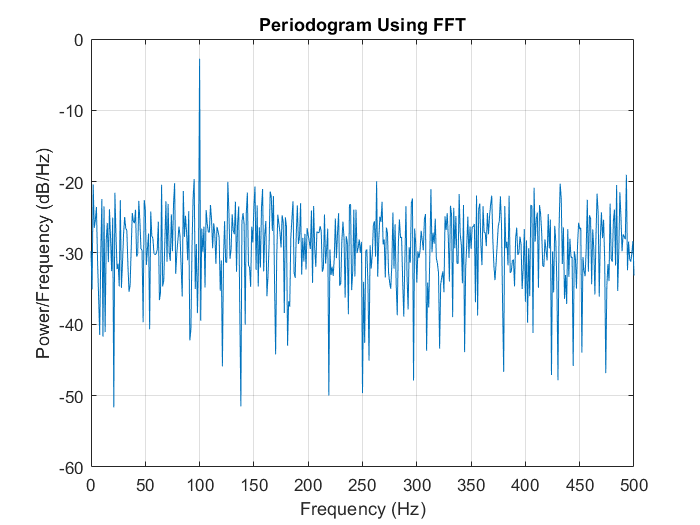

N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);
psdx = (1/(Fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/length(x):Fs/2;

plot(freq,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')

Compute and plot the periodogram using `periodogram`. Show that the two results are identical.

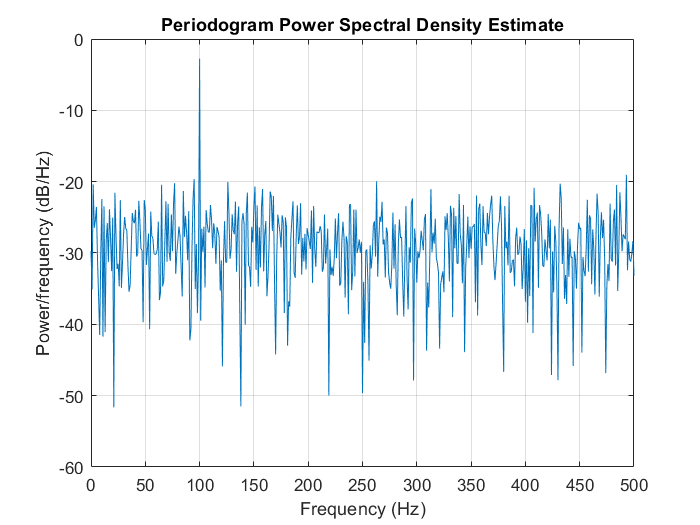

periodogram(x,rectwin(length(x)),length(x),Fs)


mxerr = max(psdx'-periodogram(x,rectwin(length(x)),length(x),Fs))

mxerr = 3.4694e-18

## Input with Normalized Frequency

Use `fft` to produce a periodogram for an input using normalized frequency. Create a signal consisting of a sine wave in *N*(0,1) additive noise. The sine wave has an angular frequency of $\pi/4$ rad/sample. Use the default settings of the random number generator for reproducible results.

rng default
n = 0:999;
x = cos(pi/4*n) + randn(size(n));

Obtain the periodogram using `fft`. The signal is real-valued and has even length. Because the signal is real-valued, you only need power estimates for the positive or negative frequencies. In order to conserve the total power, multiply all frequencies that occur in both sets -- the positive and negative frequencies -- by a factor of 2. Zero frequency (DC) and the Nyquist frequency do not occur twice. Plot the result.

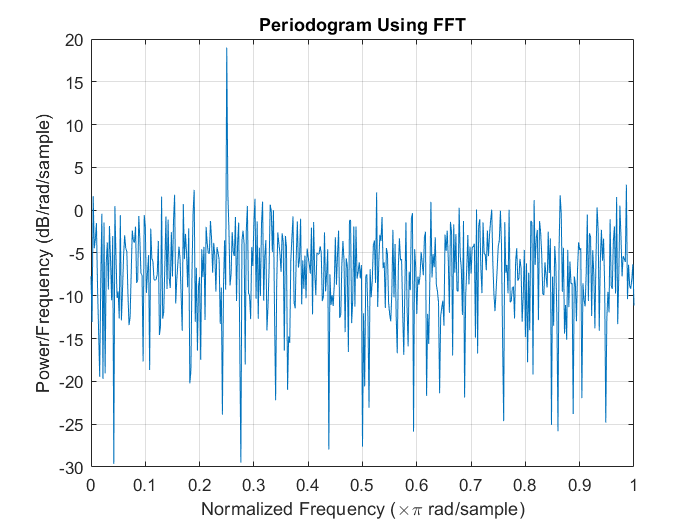

N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);
psdx = (1/(2*pi*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:(2*pi)/N:pi;

plot(freq/pi,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Normalized Frequency (\times\pi rad/sample)') 
ylabel('Power/Frequency (dB/rad/sample)')

Compute and plot the periodogram using `periodogram`. Show that the two results are identical.

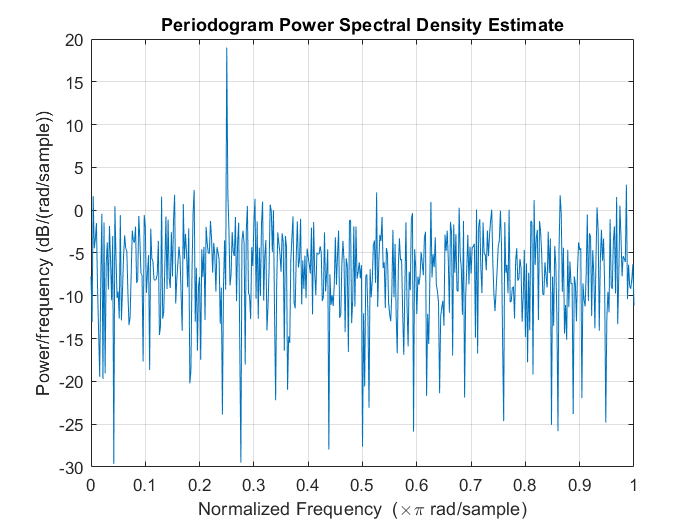

periodogram(x,rectwin(length(x)),length(x))


mxerr = max(psdx'-periodogram(x,rectwin(length(x)),length(x)))

mxerr = 1.4211e-14

## Complex-Valued Input with Normalized Frequency

Use fft to produce a periodogram for a complex-valued input with normalized frequency. The signal is a complex exponential with an angular frequency of $\pi/4$ rad/sample in complex-valued *N*(0,1) noise. Set the random number generator to the default settings for reproducible results.

rng default
n = 0:999;
x = exp(1j*pi/4*n) + [1 1j]*randn(2,length(n))/sqrt(2);

Use `fft` to obtain the periodogram. Because the input is complex-valued, obtain the periodogram from $(-\pi,\pi]$ rad/sample. Plot the result.

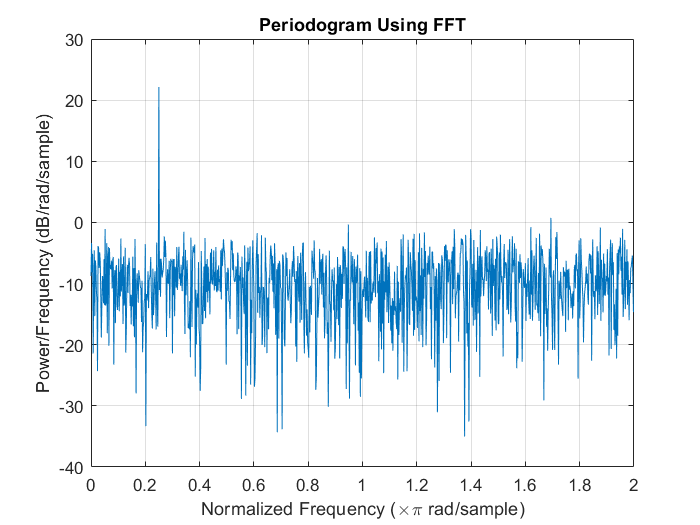

N = length(x);
xdft = fft(x);
psdx = (1/(2*pi*N)) * abs(xdft).^2;
freq = 0:(2*pi)/N:2*pi-(2*pi)/N;

plot(freq/pi,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Normalized Frequency (\times\pi rad/sample)') 
ylabel('Power/Frequency (dB/rad/sample)')

Use `periodogram` to obtain and plot the periodogram. Compare the PSD estimates.

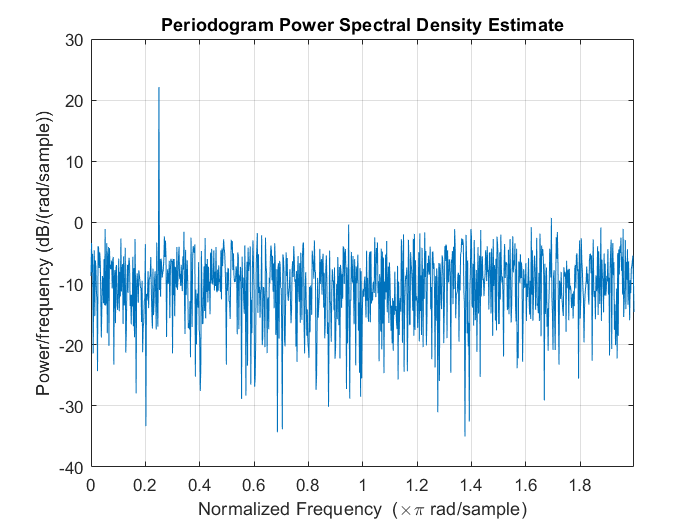

periodogram(x,rectwin(length(x)),length(x),'twosided')


mxerr = max(psdx'-periodogram(x,rectwin(length(x)),length(x),'twosided'))

mxerr = 4.4409e-16

## Example: Analyzing Cyclical Data with FFT

You can use the Fourier transform to analyze variations in data, such as an event in nature over a period time.

For almost 300 years, astronomers have tabulated the number and size of sunspots using the Zurich sunspot relative number.  Plot the Zurich number over approximately the years 1700 to 2000.

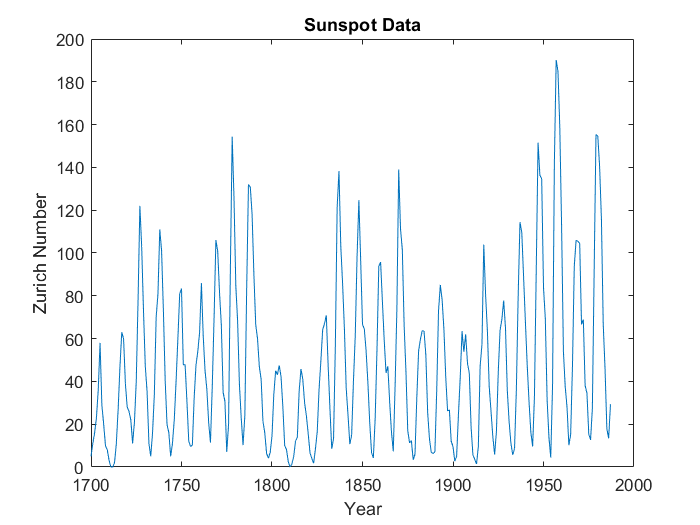

load sunspot.dat
year = sunspot(:,1);
relNums = sunspot(:,2);
plot(year,relNums)
xlabel('Year')
ylabel('Zurich Number')
title('Sunspot Data')

To take a closer look at the cyclical nature of sunspot activity, plot the first 50 years of data.

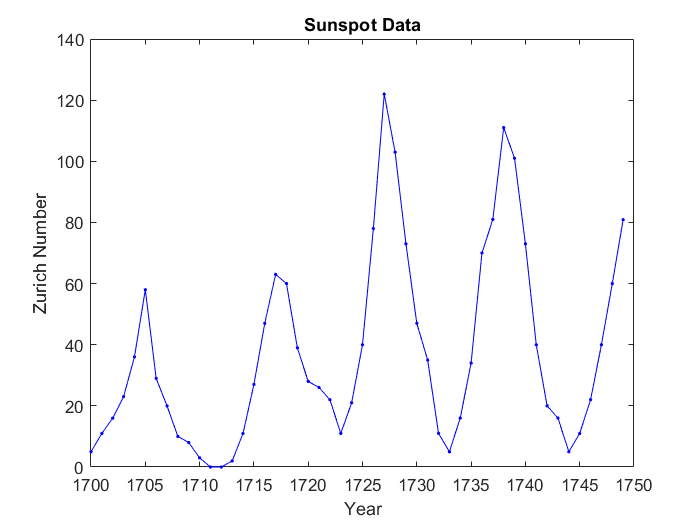

plot(year(1:50),relNums(1:50),'b.-');
xlabel('Year')
ylabel('Zurich Number')
title('Sunspot Data')

The Fourier transform is a fundamental tool in signal processing that identifies frequency components in data.  Using the `fft` function, take the Fourier transform of the Zurich data.  Remove the first element of the output, which stores the sum of the data.  Plot the remainder of the output, which contains a mirror image of complex Fourier coefficients about the real axis.  

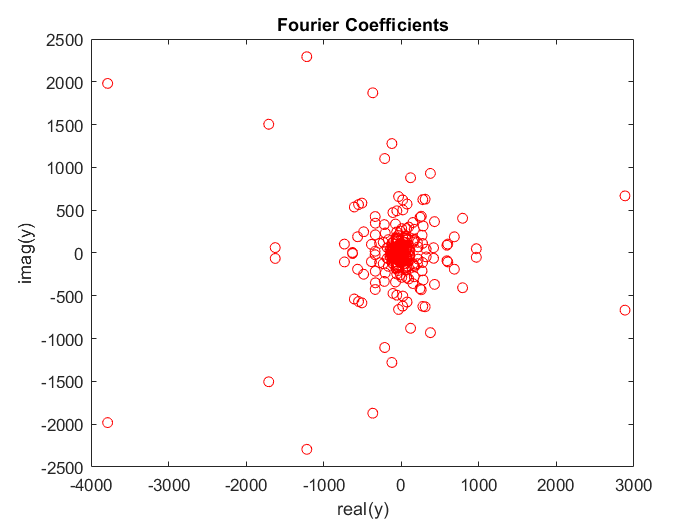

y = fft(relNums);
y(1) = [];
plot(y,'ro')
xlabel('real(y)')
ylabel('imag(y)')
title('Fourier Coefficients')

Fourier coefficients on their own are difficult to interpret.  A more meaningful measure of the coefficients is their magnitude squared, which is a measure of power.  Since half of the coefficients are repeated in magnitude, you only need to compute the  power on one half of the coefficients.  Plot the power spectrum as a function of frequency, measured in cycles per year. 

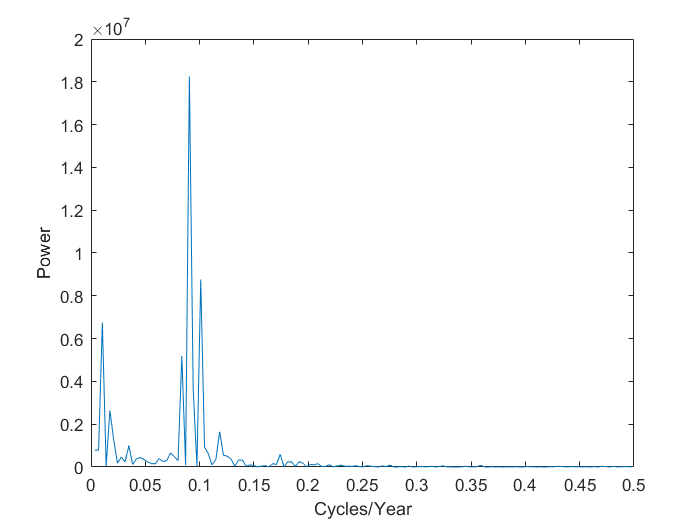

n = length(y); % Number of data points used for the FFT
power = abs(y(1:floor(n/2))).^2; % power of first half of transform data
maxfreq = 1/2;                   % maximum frequency =1/2 * fs (fs =sampling frequency =1 datapoint/year)
freq = (1:n/2)/(n/2)*maxfreq;    % equally spaced frequency grid
plot(freq,power)
xlabel('Cycles/Year')
ylabel('Power')

Maximum sunspot activity happens less frequently than once per year.  For a view of the cyclical activity that is easier to interpret, plot power as a function of period, measured in years per cycle.  The plot reveals that sunspot activity peaks about once every 11 years.    

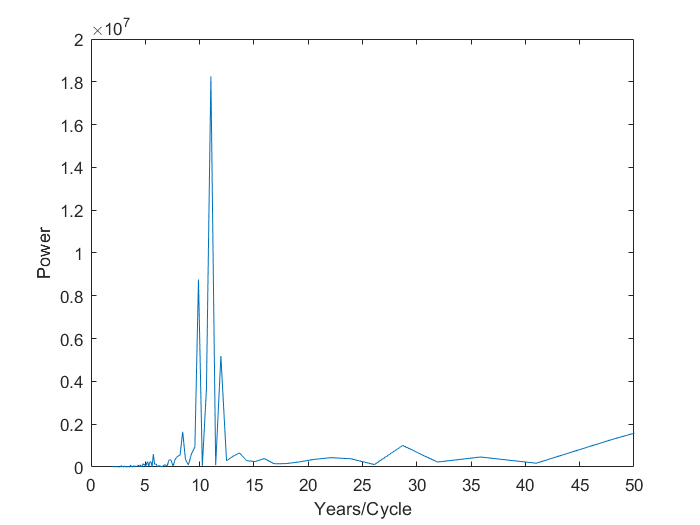

period = 1./freq;
plot(period,power);
xlim([0 50]); %zoom in on max power
xlabel('Years/Cycle')
ylabel('Power')

### *Question: Can you use the above technique to analyze audio recordings? Download `tone_432Hz.mat' or `ahhhh.mat' or `clap_once.mat' *

% clear all
% Fs = 8000;
% t = 0:1/Fs:1-1/Fs;
%load clap_once.mat
%load ahhhh.mat
%load tone_432Hz.mat
% 
% 
% y = y.';
% 
% N = length(y);
% xdft = fft(y);
% xdft = xdft(1:N/2+1);
% psdx = (1/(Fs*N)) * abs(xdft).^2;
% psdx(2:end-1) = 2*psdx(2:end-1);
% freq = 0:Fs/length(y):Fs/2;
% 
% figure
% plot(freq,10*log10(psdx))
% grid on
% title('Periodogram Using FFT')
% xlabel('Frequency (Hz)')
% ylabel('Power/Frequency (dB/Hz)')

## Example: Analyzing a sound file

% % Spetral analysis of sound recording
% %load spectral_#.mat % You need to download the file allocated to you.
% 
% Fs = 8000;
% t = 0:1/Fs:1-1/Fs;
% load spectral_1.mat  % Short recording of a guitar cord
% 
% N = length(y);
% xdft = fft(y);
% xdft = xdft(1:N/2+1);
% psdx = (1/(Fs*N)) * abs(xdft).^2;
% psdx(2:end-1) = 2*psdx(2:end-1);
% freq = 0:Fs/length(y):Fs/2;
% 
% figure
% plot(freq,10*log10(psdx))
% grid on
% title('Periodogram Using FFT')
% xlabel('Frequency (Hz)')
% ylabel('Power/Frequency (dB/Hz)')

*Pull this figure out to a separate window and magnify the lower part of the frequencies to identify the dominant  frequencies. You may be able to identify the chord.*

*Copyright 1984-2014 The MathWorks, Inc. Edited by H. Chung 2019*